# Actividad Solución de ecuaciones

## Problemas

1. Use el método de Jacobi y Gauss-Seidel para resolver el siguiente sistema de ecuaciones con una tolerancia de `tol = 0:05`. Obtenga una **gráfica de error** con los errores de los dos métodos. Si es necesario, reacomode las ecuaciones para lograr convergencia (con la intención de que la matriz de coeficientes sea diagonal dominante). Valide la solución utilizando Gauss-Jordan.


$$ \begin{array} {ccc} 
2x_1-6x_2-x_3&= & -38 \\
-3x_1-x_2+7x_3&= & -34 \\
-8x_1+x_2-2x_3&= & -20
\end{array}
$$


## Solución

Se tiene primeramente que verficar si el sistema en su fora dada resulta en una matriz diagonal dominante, es decir: 


$$|a_{ii}|>\sum_{j=1,j\neq i}^{n} |a_{ij}|  $$


Revisando el valor de $i$ con la **forma orginal** del sistema

 
$$i=1\longrightarrow \;\left|2\right|>\left|-7\right|\cdots \textrm{no}\;\textrm{cumple}\;y\;\textrm{hay}\;\textrm{que}\;\textrm{realizar}\;\textrm{un}\;\textrm{cambio}$$


Haciendo el cambio de $F_1 \iff F_2$ y $F_2 \iff F_3$ 


$$ \begin{array} {ccc} 
-8x_1+x_2-2x_3&= & -20\\
2x_1-6x_2-x_3&= & -38 \\
-3x_1-x_2+7x_3&= & -34 
\end{array}$$


Revisando el valor de $i$ con la **forma modificada** del sistema

 
$$i=1\longrightarrow \;\left|8\right|>\left|-1\right|\cdots \textrm{cumple}$$


 
$$i=2\longrightarrow \;\left|-6\right|>\left|1\right|\cdots \textrm{cumple}$$


 
$$i=3\longrightarrow \;\left|7\right|>\left|-4\right|\cdots \textrm{cumple}$$


Nuestro sistema ahora **sí** resulta en una matriz diagonal dominante de forma:


$$\left\lbrack \begin{array}{ccc}
-8x_1  & x_2  & -{2x}_3 \\
-3x_1  & -x_2  & 7x_3 \\
2x_1  & {-6x}_2  & -x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-38\\
-34\\
-20
\end{array}\right\rbrack$$


Y ya pasando a código nos resulta en:

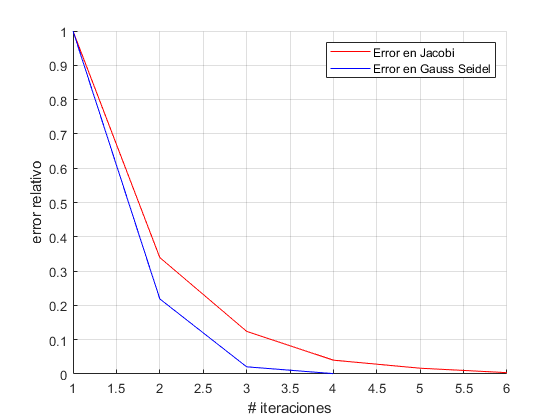

A = [-8 1 -2; 2 -6 -1; -3 -1 7];
b = [-20 -38 -34]';

tol = 0.05;

[xJa, iJa, errorJa] = metodoJacobi([0 0 0]', A, b, 50, tol);
[xGaS, iGaS, errorGaS] = metodoGaussSeidel([0 0 0]', A, b, 50, tol);

figure (1)
hold on
grid on 
xlabel("# iteraciones");
ylabel("error relativo");
plot(1:iJa, errorJa, '-r');
plot(1:iGaS, errorGaS, '-b');

legend("Error en Jacobi", "Error en Gauss Seidel");


[x] = metodoGaussJordan(A, b);

    1.0000   -0.1250    0.2500    2.5000
    2.0000   -6.0000   -1.0000  -38.0000
   -3.0000   -1.0000    7.0000  -34.0000

    1.0000   -0.1250    0.2500    2.5000
         0   -5.7500   -1.5000  -43.0000
   -3.0000   -1.0000    7.0000  -34.0000

    1.0000   -0.1250    0.2500    2.5000
         0   -5.7500   -1.5000  -43.0000
         0   -1.3750    7.7500  -26.5000

    1.0000   -0.1250    0.2500    2.5000
         0    1.0000    0.2609    7.4783
         0   -1.3750    7.7500  -26.5000

    1.0000         0    0.2826    3.4348
         0    1.0000    0.2609    7.4783
         0   -1.3750    7.7500  -26.5000

    1.0000         0    0.2826    3.4348
         0    1.0000    0.2609    7.4783
         0         0    8.1087  -16.2174

    1.0000         0    0.2826    3.4348
         0    1.0000    0.2609    7.4783
         0         0    1.0000   -2.0000

    1.0000         0         0    4.0000
         0    1.0000    0.2609    7.4783
         0         0    1.0000   -2.0000

    1.00

## Conclusión

El método de Gauss-Seidel obtuvo un mejor resultado en menos iteraciones